Zczytanie danych z układu rzeczywistego oraz dopasowanie wzmocnienia oraz stałej czasowej za pomocą funckji nlinfit

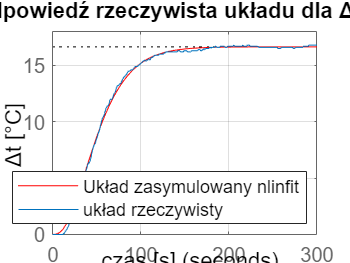

clc;clear all;
Dane=readmatrix("MZ.txt","Delimiter","\t","DecimalSeparator",",");
deltau=30;
t1=Dane(:,2);
F=Dane(:,5);
Moc=Dane(:,6);
for i=1:length(Moc)
   if(Moc(i)>=60)
   break     
   end
end
czas=[0:0.5:(length(Moc)-i)/2];
pom=1;
for j=i:length(t1)
deltatemp2(pom)=t1(j)-t1(1);
pom=pom+1;
end
kpom=17/30; %delta t/ detla u
Tpom=30; %delta u
beta0=[kpom Tpom];
modelfun=@(b,x)(b(1)*deltau-((b(1)*deltau*x.^2)/(2*b(2)^2)).*exp(-x/b(2))-(b(1)*deltau*x/b(2)).*exp(-x/b(2))-(b(1)*deltau).*exp(-x/b(2)));
beta=nlinfit(czas,deltatemp2,modelfun,beta0);
T=beta(2); %stała czasowa
k= beta(1); %wzmocnienie
s=tf('s');
K=k/(s*T+1)/(s*T+1)/(s*T+1);
step(K*deltau,300,'red');
hold on
plot(czas,deltatemp2);
hold off
title('Odpowiedź rzeczywista układu dla ΔU=30');
legend('Układ zasymulowany nlinfit','układ rzeczywisty',"Location","southeast");
xlabel('czas [s]');
ylabel('Δt [°C]');
grid on

Wygenerowanie danych dla czasu próbkowania Ts=1[s]

czasik=300;%czas
k=0.5548; %obliczone k
T=18.1708; %obliczone T
N=300; %ilość kroków 
Umin=-30; %minimalna wartość sterowania
Umax=70; %maksymalna wartość sterowania
yzad=16.8;%47; %wartość zadana 
ywarpocz=0;%30.2; %wartość początkowa
Ts=czasik/N; %okres próbkowania
H=zeros(4*N+7, 4*N+7); %N+1 u+N+2 x1+N+2 x2+N+2 x3
g=zeros(4*N+7,1); ;%N+1 u+N+2 x1+N+2 x2+N+2 x3
A=zeros(3*N+6, 4*N+7); 
lbA=zeros(3*N+6,1);
lbA(3*N+4)=ywarpocz;%x1 0
ubA=lbA; % przerabiamy nierównośc na równanie
R=0.1;
Q=1;
ub=ones(4*N+7,1)*Umax; %ograniczenia nierównościowe górne
lb=ones(4*N+7,1)*Umin;%ograniczenia nierównościowe dolne
for i=N+2:4*N+7 %usuniecie ograniczen z x1,x2,x3
   ub(i)=+inf; 
   lb(i)=-inf;
end
for i=1:N+1     %ograniczenia hasjanowe na U
    H(i,i)=2*R;    %przekatna ui
    if (i<N+1 && i>1)
    H(i,i)=4*R;   %przekatna u i+1
    end
    if (i<N+1)
    H(i,i+1)=-2*R; %na prawo od przekątnej
    H(i+1,i)=-2*R; %w dół od przekątnej
    end
end
for i=N+2:2*N+3
   H(i,i)=2*Q; %Hesjan
   g(i)=-2*yzad; %inaczej f
end
for i=1:N+1 %A
    A(i,i+N+1)=-1/Ts;%x1i
    A(i,i+N+2)=1/Ts;%x1i+1
    A(i,i+2*N+4)=-1;%x2i+1
    A(i+N+1,i+2*N+3)=-1/Ts;%x2i
    A(i+N+1,i+2*N+4)=1/Ts;%x2i+1
    A(i+N+1,i+3*N+6)=-1;%x3i+1
    A(i+2*N+2,i+3*N+6)=(1/Ts)+(3/T);%x3i+1
    A(i+2*N+2,i+3*N+5)=-1/Ts;%x3i
    A(i+2*N+2,i+2*N+4)=3/T^2;%x2i+1
    A(i+2*N+2,i+N+2)=1/T^3;%x1i+1
    A(i+2*N+2,i)=-k/T^3;%u
end
A(3*N+4,N+2)=1; % ograniczenie początkowe na x1
A(3*N+5,2*N+4)=1; %ograniczenie początkowe na x2
A(3*N+6,3*N+6)=1; %ograniczenie początkowe na x3
time300=0:Ts:czasik; %wektor czasu do generowania wykresów

Wywołanie funkcji quadprog oraz qpOASES dla Ts=1 [s]

x0= zeros(4*N+7,1);
options = optimoptions('quadprog','Algorithm','active-set','Display',"none",'MaxIterations',10000);
opcje=qpOASES_options('maxIter',10000,'terminationTolerance',1e-8,'boundTolerance',1e-8);
auxinput=qpOASES_auxInput('x0',x0);
tic
y1n300=quadprog(H,g,[],[],A,lbA,lb,ub,x0,options);
czasquadprog300=toc

czasquadprog300 = 0.2484

tic
yn300=qpOASES(H,g,A,lb,ub,lbA,ubA,opcje,auxinput);
czasqpOASES300=toc

czasqpOASES300 = 527.6454

Generacja wykresów porównania odpowiedzi skokowej oraz sygnału sterowania dla Ts=1 [s]

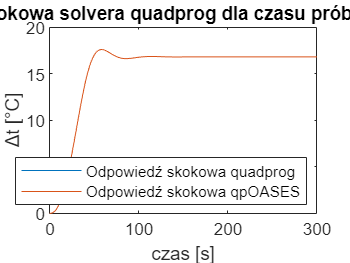

figure;
plot(time300,y1n300(N+2:2*N+2));
hold on
plot(time300,yn300(N+2:2*N+2));
legend('Odpowiedź skokowa quadprog','Odpowiedź skokowa qpOASES',"Location","southeast");
xlabel('czas [s]');
ylabel('Δt [°C]');
title('Odpowiedź skokowa solvera quadprog dla czasu próbkowania Ts=1[s]');

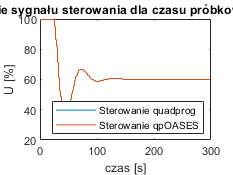


figure;
stairs(time300,y1n300(1:N+1)+30);
hold on
stairs(time300,yn300(1:N+1)+30);
legend('Sterowanie quadprog','Sterowanie qpOASES',"Location","southeast");
xlabel('czas [s]');
ylabel('U [%]');
title('Porównanie sygnału sterowania dla czasu próbkowania Ts=1[s]');

%macierzU=yn300(1:N+1,1); %stworzenie macierzy U
%writematrix(macierzU+30,'macierzUN=300.txt') %zapis do pliku 

Zapis wyników do tabeli w celu łatwiejszego porównania rezultatów

co=cellstr(string('u:')+(1:N+1));
for i=N+2:4*N+7
    if(i>=N+2 && i<=2*N+3)
      co(i)=cellstr("X1:"+num2str(i-(N+2)));
    elseif(i>=2*N+4 && i<=3*N+5)
      co(i)=cellstr("X2:"+num2str(i-(2*N+4)));
    elseif (i>=3*N+6 && i<=4*N+7)
      co(i)=cellstr("X3:"+num2str(i-(3*N+6))); 
    end
end
wynikN300= table(yn300,y1n300,co');

Porównanie danych zasymulowanych z rzeczyswistymi dla Ts=1 [s]

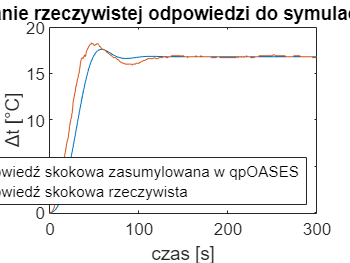

Dane=readmatrix("MZN=300.txt","Delimiter","\t","DecimalSeparator",",");
t1=Dane(:,2);
for i=1:length(t1)
   if(t1(i)>=31.3)
   break     
   end
end
i=i-6;
czasN300=[0:0.5:(length(t1)-i)/2];
czasqp300=[0:Ts:300];
pom=1;
for j=i:length(t1)
dt1N300(pom)=t1(j)-31.2;
pom=pom+1;
end
% plot(czasN300,dt1N300);
% title('Odpowiedź skokowa układu rzeczywistego dla Ts=1 [s]')
% xlabel('czas [s]');
% ylabel('Δt [°C]');
% hold off
figure;
plot(time300,yn300(N+2:2*N+2));
hold on
plot(czasN300,dt1N300);
hold off
title('Porównanie rzeczywistej odpowiedzi do symulacji Ts=1 [s]')
legend('Odpowiedź skokowa zasumylowana w qpOASES','Odpowiedź skokowa rzeczywista',"Location","southeast");
xlabel('czas [s]');
ylabel('Δt [°C]');

Wygenerowanie danych dla czasu próbkowania Ts=5[s]

czasik=300;%czas
k=0.5548; %obliczone k
T=18.1708; %obliczone T
N=60; %ilość kroków 
Umin=-30; %minimalna wartość sterowania
Umax=70; %maksymalna wartość sterowania
yzad=16.8;%47; %wartość zadana 
ywarpocz=0;%30.2; %wartość początkowa
Ts=czasik/N; %okres próbkowania
H=zeros(4*N+7, 4*N+7);%N+1 u+N+2 x1+N+2 x2+N+2 x3
g=zeros(4*N+7,1);
A=zeros(3*N+6, 4*N+7);
lbA=zeros(3*N+6,1);
lbA(3*N+4)=ywarpocz;%x1 0
ubA=lbA; %równościowe
R=0.1;
Q=1;
ub=ones(4*N+7,1)*Umax; %ograniczenia nierównościowe górne
lb=ones(4*N+7,1)*Umin;%ograniczenia nierównościowe dolne
for i=N+2:4*N+7 %usuniecie ograniczen z x1,x2,x3
   ub(i)=+inf; 
   lb(i)=-inf;
end
for i=1:N+1     %ograniczenia hasjanowe na U
    H(i,i)=2*R;    %przekatna ui
    if (i<N+1 && i>1)
    H(i,i)=4*R;   %przekatna u i+1
    end
    if (i<N+1)
    H(i,i+1)=-2*R;
    H(i+1,i)=-2*R;
    end

end
for i=N+2:2*N+3
   H(i,i)=2*Q; %Hesjan
   g(i)=-2*yzad; %inaczej f
end
for i=1:N+1 %A
    A(i,i+N+1)=-1/Ts;%x1i
    A(i,i+N+2)=1/Ts;%x1i+1
    A(i,i+2*N+4)=-1;%x2i+1
    A(i+N+1,i+2*N+3)=-1/Ts;%x2i
    A(i+N+1,i+2*N+4)=1/Ts;%x2i+1
    A(i+N+1,i+3*N+6)=-1;%x3i+1
    A(i+2*N+2,i+3*N+6)=(1/Ts)+(3/T);%x3i+1
    A(i+2*N+2,i+3*N+5)=-1/Ts;%x3i
    A(i+2*N+2,i+2*N+4)=3/T^2;%x2i+1
    A(i+2*N+2,i+N+2)=1/T^3;%x1i+1
    A(i+2*N+2,i)=-k/T^3;%u
end
A(3*N+4,N+2)=1; % ograniczenie początkowe na x1
A(3*N+5,2*N+4)=1; %ograniczenie początkowe na x2
A(3*N+6,3*N+6)=1; %ograniczenie początkowe na x3
time60=0:Ts:czasik; %wektor czasu do generowania wykresów

Wywołanie funkcji quadprog oraz qpOASES dla Ts=5 [s]

x0= zeros(4*N+7,1);
options = optimoptions('quadprog','Algorithm','active-set','Display',"none",'MaxIterations',10000);
opcje=qpOASES_options('maxIter',10000,'terminationTolerance',1e-8,'boundTolerance',1e-8);
auxinput=qpOASES_auxInput('x0',x0);
tic
yn60=qpOASES(H,g,A,lb,ub,lbA,ubA,opcje,auxinput);
czasqpOASES60=toc

czasqpOASES60 = 1.5524

tic
y1n60= quadprog(H,g,[],[],A,lbA,lb,ub,x0,options);
czasquad60=toc

czasquad60 = 0.0606

Generacja wykresów porównania odpowiedzi skokowej oraz sygnału sterowania dla Ts=5 [s]

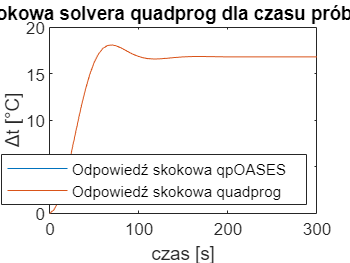

figure;
plot(time60,yn60(N+2:2*N+2));
 hold on
plot(time60,y1n60(N+2:2*N+2));
hold off
legend('Odpowiedź skokowa qpOASES','Odpowiedź skokowa quadprog',"Location","southeast");
xlabel('czas [s]');
ylabel('Δt [°C]');
title('Odpowiedź skokowa solvera quadprog dla czasu próbkowania Ts=5[s]');

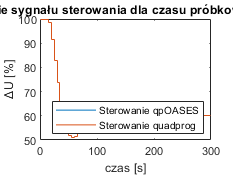


figure;
stairs(time60,yn60(1:N+1)+30);
hold on
stairs(time60,y1n60(1:N+1)+30);
hold off
legend('Sterowanie qpOASES','Sterowanie quadprog',"Location","southeast");
xlabel('czas [s]');
ylabel('ΔU [%]');
title('Porównanie sygnału sterowania dla czasu próbkowania Ts=5[s]');

%macierzU=yn60(1:N+1,1); %stworzenie macierzy U
%writematrix(macierzU+30,'macierzUN=60.txt') %zapis do pliku 

Zapis wyników do tabeli w celu łatwiejszego porównania resultatów

co=cellstr(string('u:')+(1:N+1));
for i=N+2:4*N+7
    if(i>=N+2 && i<=2*N+3)
      co(i)=cellstr("X1:"+num2str(i-(N+2)));
    elseif(i>=2*N+4 && i<=3*N+5)
      co(i)=cellstr("X2:"+num2str(i-(2*N+4)));
    elseif (i>=3*N+6 && i<=4*N+7)
      co(i)=cellstr("X3:"+num2str(i-(3*N+6))); 
    end
end
wynikN60= table(yn60,y1n60,co');

Porównanie danych zasymulowanych z rzeczyswistymi dla Ts=5 [s]

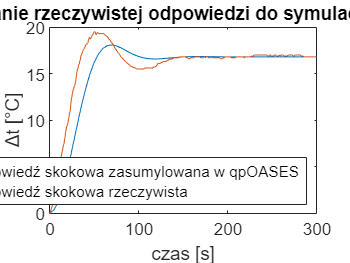

Dane=readmatrix("MZN=60.txt","Delimiter","\t","DecimalSeparator",",");
t2=Dane(:,2);
for i=1:length(t2)
   if(t2(i)>=31.3)
   break     
   end
end
i=i-2;
czasN60=[0:0.5:(length(t2)-i)/2];
pom=1;
for j=i:length(t2)
dt1N60(pom)=t2(j)-31.1;
pom=pom+1;
end
% plot(czasN60,dt1N60);
% title('Odpowiedź skokowa układu rzeczywistego dla Ts=5 [s]')
% xlabel('czas [s]');
% ylabel('Δt [°C]');

figure;
plot(time60,yn60(N+2:2*N+2));
hold on
plot(czasN60,dt1N60);
hold off
title('Porównanie rzeczywistej odpowiedzi do symulacji Ts=5 [s]')
legend('Odpowiedź skokowa zasumylowana w qpOASES','Odpowiedź skokowa rzeczywista',"Location","southeast");
xlabel('czas [s]');
ylabel('Δt [°C]');

Wygenerowanie danych dla czasu próbkowania Ts=10[s]

czasik=300;%czas
k=0.5548; %obliczone k
T=18.1708; %obliczone T
N=30; %ilość kroków 
Umin=-30; %minimalna wartość sterowania
Umax=70; %maksymalna wartość sterowania
yzad=16.8;%47; %wartość zadana 
ywarpocz=0;%30.2; %wartość początkowa
Ts=czasik/N; %okres próbkowania
H=zeros(4*N+7, 4*N+7);%N+1 u+N+2 x1+N+2 x2+N+2 x3
g=zeros(4*N+7,1);
A=zeros(3*N+6, 4*N+7);
lbA=zeros(3*N+6,1);
lbA(3*N+4)=ywarpocz;%x1 0
ubA=lbA; %równościowe
R=0.1;
Q=1;
ub=ones(4*N+7,1)*Umax; %ograniczenia nierównościowe górne
lb=ones(4*N+7,1)*Umin;%ograniczenia nierównościowe dolne
for i=N+2:4*N+7 %usuniecie ograniczen z x1,x2,x3
   ub(i)=+inf; 
   lb(i)=-inf;
end
for i=1:N+1     %ograniczenia hasjanowe na U
    H(i,i)=2*R;    %przekatna ui
    if (i<N+1 && i>1)
    H(i,i)=4*R;   %przekatna u i+1
    end
    if (i<N+1)
    H(i,i+1)=-2*R;
    H(i+1,i)=-2*R;
    end

end
for i=N+2:2*N+3
   H(i,i)=2*Q; %Hesjan
   g(i)=-2*yzad; %inaczej f
end
for i=1:N+1 %A
    A(i,i+N+1)=-1/Ts;%x1i
    A(i,i+N+2)=1/Ts;%x1i+1
    A(i,i+2*N+4)=-1;%x2i+1
    A(i+N+1,i+2*N+3)=-1/Ts;%x2i
    A(i+N+1,i+2*N+4)=1/Ts;%x2i+1
    A(i+N+1,i+3*N+6)=-1;%x3i+1
    A(i+2*N+2,i+3*N+6)=(1/Ts)+(3/T);%x3i+1
    A(i+2*N+2,i+3*N+5)=-1/Ts;%x3i
    A(i+2*N+2,i+2*N+4)=3/T^2;%x2i+1
    A(i+2*N+2,i+N+2)=1/T^3;%x1i+1
    A(i+2*N+2,i)=-k/T^3;%u
end
A(3*N+4,N+2)=1; % ograniczenie początkowe na x1
A(3*N+5,2*N+4)=1; %ograniczenie początkowe na x2
A(3*N+6,3*N+6)=1; %ograniczenie początkowe na x3
time30=0:Ts:czasik; %wektor czasu do generowania wykresów

Wywołanie funkcji quadprog oraz qpOASES dla Ts=10 [s]

x0= zeros(4*N+7,1);
options = optimoptions('quadprog','Algorithm','active-set','Display',"none",'MaxIterations',10000);
opcje=qpOASES_options('maxIter',10000,'terminationTolerance',1e-8,'boundTolerance',1e-8);
auxinput=qpOASES_auxInput('x0',x0);
tic
yn30=qpOASES(H,g,A,lb,ub,lbA,ubA,opcje,auxinput);
czasqpOASES30=toc

czasqpOASES30 = 0.1007

tic
y1n30 = quadprog(H,g,[],[],A,lbA,lb,ub,x0,options);
czasquad30=toc

czasquad30 = 0.0220

Generacja wykresów porównania odpowiedzi skokowej oraz sygnału sterowania dla Ts=10 [s]

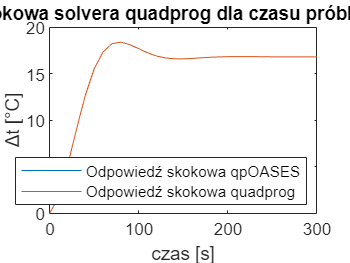

figure;
plot(time30,yn30(N+2:2*N+2));
 hold on
plot(time30,y1n30(N+2:2*N+2));
hold off
legend('Odpowiedź skokowa qpOASES','Odpowiedź skokowa quadprog',"Location","southeast");
xlabel('czas [s]');
ylabel('Δt [°C]');
title('Odpowiedź skokowa solvera quadprog dla czasu próbkowania Ts=10[s]');

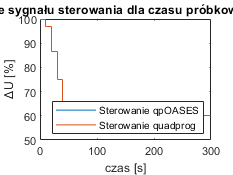


figure;
stairs(time30,yn30(1:N+1)+30);
hold on
stairs(time30,y1n30(1:N+1)+30);
hold off
legend('Sterowanie qpOASES','Sterowanie quadprog',"Location","southeast");
xlabel('czas [s]');
ylabel('ΔU [%]');
title('Porównanie sygnału sterowania dla czasu próbkowania Ts=10[s]');

%macierzU=yn30(1:N+1,1); %stworzenie macierzy U
%writematrix(macierzU+30,'macierzUN=30.txt') %zapis do pliku 

Zapis wyników do tabeli w celu łatwiejszego porównania resultatów

co=cellstr(string('u:')+(1:N+1));
for i=N+2:4*N+7
    if(i>=N+2 && i<=2*N+3)
      co(i)=cellstr("X1:"+num2str(i-(N+2)));
    elseif(i>=2*N+4 && i<=3*N+5)
      co(i)=cellstr("X2:"+num2str(i-(2*N+4)));
    elseif (i>=3*N+6 && i<=4*N+7)
      co(i)=cellstr("X3:"+num2str(i-(3*N+6))); 
    end
end
wynikN30= table(yn30,y1n30,co');

Porównanie danych zasymulowanych z rzeczyswistymi dla Ts=10 [s]

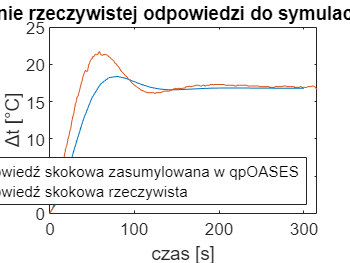

Dane=readmatrix("MZN=30.txt","Delimiter","\t","DecimalSeparator",",");
t3=Dane(:,2);
for i=1:length(t3)
   if(t3(i)>=31.3)
   break     
   end
end
i=i-2;
czasN30=[0:0.5:(length(t3)-i)/2];
pom=1;
for j=i:length(t3)
dt1N30(pom)=t3(j)-31.1;
pom=pom+1;
end
% figure;
% plot(czasN30,dt1N30);
% title('Odpowiedź skokowa układu rzeczywistego dla Ts=10 [s]')
% xlabel('czas [s]');
% ylabel('Δt [°C]');

figure;
plot(time30,yn30(N+2:2*N+2));
hold on
plot(czasN30,dt1N30);
hold off
title('Porównanie rzeczywistej odpowiedzi do symulacji Ts=10 [s]')
legend('Odpowiedź skokowa zasumylowana w qpOASES','Odpowiedź skokowa rzeczywista',"Location","southeast");
xlabel('czas [s]');
ylabel('Δt [°C]');

Porównanie odpowiedzi układów rzeczywistych

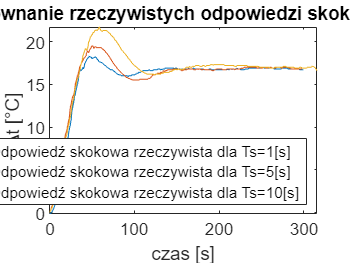

figure;
plot(czasN300,dt1N300);
hold on
plot(czasN60,dt1N60);
hold on
plot(czasN30,dt1N30);
hold off
title('Porównanie rzeczywistych odpowiedzi skokowych')
legend('Odpowiedź skokowa rzeczywista dla Ts=1[s]','Odpowiedź skokowa rzeczywista dla Ts=5[s]','Odpowiedź skokowa rzeczywista dla Ts=10[s]',"Location","southeast");
xlabel('czas [s]');
ylabel('Δt [°C]');

Porównanie sterowań

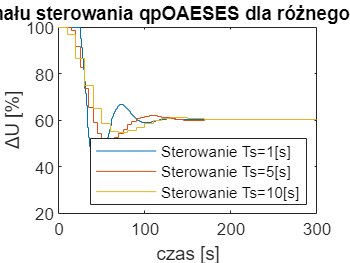

figure;
stairs(time300,yn300(1:300+1)+30);
hold on
stairs(time60,yn60(1:60+1)+30);
hold on
stairs(time30,yn30(1:30+1)+30);
hold on
legend('Sterowanie Ts=1[s]','Sterowanie Ts=5[s]','Sterowanie Ts=10[s]',"Location","southeast");
xlabel('czas [s]');
ylabel('ΔU [%]');
title('Porównanie sygnału sterowania qpOAESES dla różnego czasu próbkowania');